% quintic poly from EXAM JAN 2020 Ex 3

A = [5.2, 1.5]'

A =     5.2000
    1.5000


Ax = A(1);
Ay = A(2);

B = [2.2, -2.5]'

B =     2.2000
   -2.5000


Bx = B(1);
By = B(2);

v = 2.5

v = 2.5000


alpha_a = -60

alpha_a = -60

alpha_b = 30

alpha_b = 30


T = 2;

vel = v * (B-A)/norm(B-A);
vx = vel(1)

vx = -1.5000

vy = vel(2)

vy = -2

syms t real
tau = t/T

$$tau = \frac{t}{2}$$

% Sx
s_0 = 0;
s_1 = 1;

s_0_dot = vx/(Bx-Ax);
s_1_dot = 0;

s_0_dd = 0;
s_1_dd = 0;

[a, b, c, d, e, f] = quintic_poly_compute_coeff(s_0, s_1, s_0_dot, s_1_dot, s_0_dd, s_1_dd, T, false)

a = 3

b = -7

c = 4

d = 0

e = 1

f = 0

sx = quintic_poly(a, b, c, d, e, f, tau)

$$sx = \frac{3\,t^{5}}{32}-\frac{7\,t^{4}}{16}+\frac{t^{3}}{2}+\frac{t}{2}$$

% Sy
s_0 = 0;
s_1 = 1;

s_0_dot = vy/(By-Ay);
s_1_dot = 0;

s_0_dd = 0;
s_1_dd = 0;

[a, b, c, d, e, f] = quintic_poly_compute_coeff(s_0, s_1, s_0_dot, s_1_dot, s_0_dd, s_1_dd, T, false)

a = 3

b = -7

c = 4

d = 0

e = 1

f = 0

sy = quintic_poly(a, b, c, d, e, f, tau)

$$sy = \frac{3\,t^{5}}{32}-\frac{7\,t^{4}}{16}+\frac{t^{3}}{2}+\frac{t}{2}$$

S = [sx, sy]'

$$S = \left(\begin{array}{c} \frac{3\,t^{5}}{32}-\frac{7\,t^{4}}{16}+\frac{t^{3}}{2}+\frac{t}{2}\\ \frac{3\,t^{5}}{32}-\frac{7\,t^{4}}{16}+\frac{t^{3}}{2}+\frac{t}{2} \end{array}\right)$$

p_t = A + (B-A).*S

$$p\_t = \left(\begin{array}{c} -\frac{9\,t^{5}}{32}+\frac{21\,t^{4}}{16}-\frac{3\,t^{3}}{2}-\frac{3\,t}{2}+\frac{26}{5}\\ -\frac{3\,t^{5}}{8}+\frac{7\,t^{4}}{4}-2\,t^{3}-2\,t+\frac{3}{2} \end{array}\right)$$

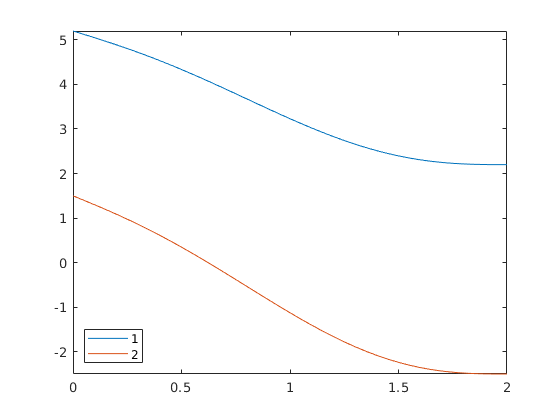

plot_function(p,t, [0, T])

v_t = diff(p_t, t)

$$v\_t = \left(\begin{array}{c} -\frac{45\,t^{4}}{32}+\frac{21\,t^{3}}{4}-\frac{9\,t^{2}}{2}-\frac{3}{2}\\ -\frac{15\,t^{4}}{8}+7\,t^{3}-6\,t^{2}-2 \end{array}\right)$$

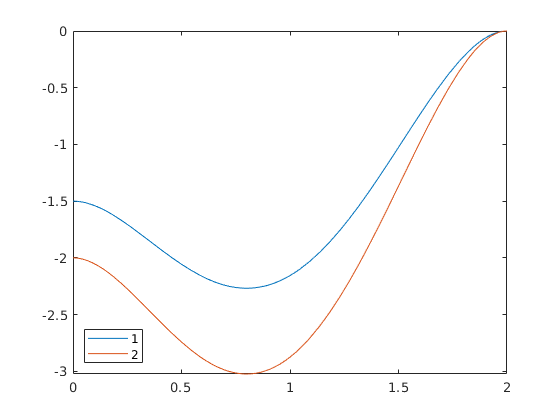

plot_function(v_t, t, [0, T])

a_t = diff(v_t, t)

$$a\_t = \left(\begin{array}{c} -\frac{45\,t^{3}}{8}+\frac{63\,t^{2}}{4}-9\,t\\ -\frac{15\,t^{3}}{2}+21\,t^{2}-12\,t \end{array}\right)$$

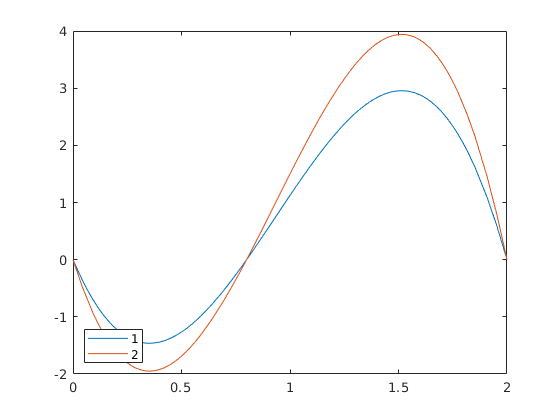

plot_function(a_t, t, [0, T])